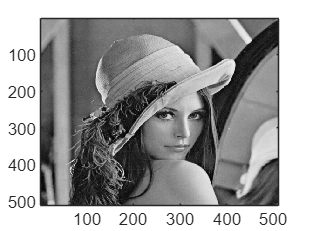

clear all
close all
img = im2double(imread("standard_test_images\lena_gray_512.tif"));
img = img(:,:,1);
colormap gray
imagesc(img)

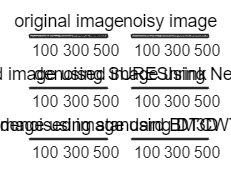

Error: profile not found! Returning default profile.


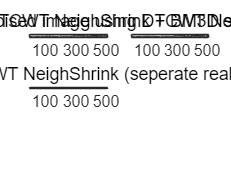

    "noise variance:"    "40.319"

    "noisy image PSNR/SSIM:"    "16.0267"    " / "    "0.30309"

    "PSNR/SSIM after SURE:"    "23.2952"    " / "    "0.56379"

    "PSNR/SSIM after NeighShrink:"    "23.3005"    " / "    "0.54982"

    "PSNR/SSIM after standard BM3D:"    "24.5957"    " / "    "0.63669"

    "PSNR/SSIM after CWT Neighshrink + BM3D second stage:"    "24.46"    " / "    "0.63964"

    "PSNR/SSIM after CWT Neighshrink + BM3D:"    "23.6258"    " / "    "0.54519"

    "PSNR/SSIM after CWT NeighShrink:"    "23.9588"    " / "    "0.59068"

    "PSNR/SSIM after CWT NeighShrink (seperate real and imag parts):"    "23.6918"    " / "    "0.56742"



noise_var = 0.025;
[PSNR,SNR,ssim,img_den] = den_compare(img,noise_var,0);

sweep_std = 10:5:50;
sweep_var = (sweep_std./255).^2;
PSNR_noisy = zeros(1,length(sweep_var));
PSNR_sure = zeros(1,length(sweep_var));
PSNR_neigh = zeros(1,length(sweep_var));
PSNR_BM3D_standard = zeros(1,length(sweep_var));
PSNR_neigh_complex = zeros(1,length(sweep_var));
PSNR_BM3D_complex_2nd = zeros(1,length(sweep_var));
PSNR_BM3D_complex = zeros(1,length(sweep_var));
PSNR_neigh_complex_real_imag = zeros(1,length(sweep_var));

SSIM_noisy = zeros(1,length(sweep_var));
SSIM_sure = zeros(1,length(sweep_var));
SSIM_neigh = zeros(1,length(sweep_var));
SSIM_BM3D_standard = zeros(1,length(sweep_var));
SSIM_neigh_complex = zeros(1,length(sweep_var));
SSIM_BM3D_complex_2nd = zeros(1,length(sweep_var));
SSIM_BM3D_complex = zeros(1,length(sweep_var));
SSIM_neigh_complex_real_imag = zeros(1,length(sweep_var));

%for var=sweep_var
parfor i=1:length(sweep_var)
    [PSNR_t,SNR_t,SSIM_t,~] = den_compare(img,sweep_var(i),0);
    close all
    %PSNR_noisy(cnt) = PSNR_t(1);
    PSNR_noisy(i) = PSNR_t(1);
    PSNR_sure(i) = PSNR_t(2)-PSNR_t(1);
    PSNR_neigh(i) = PSNR_t(3)-PSNR_t(1);
    PSNR_BM3D_standard(i) = PSNR_t(4)-PSNR_t(1);
    PSNR_neigh_complex(i) = PSNR_t(5)-PSNR_t(1);
    PSNR_BM3D_complex_2nd(i) = PSNR_t(6)-PSNR_t(1);
    PSNR_BM3D_complex(i) = PSNR_t(7)-PSNR_t(1);
    PSNR_neigh_complex_real_imag(i) = PSNR_t(8)-PSNR_t(1);

    SSIM_noisy(i) = SSIM_t(1);
    SSIM_sure(i) = SSIM_t(2)-SSIM_t(1);
    SSIM_neigh(i) = SSIM_t(3)-SSIM_t(1);
    SSIM_BM3D_standard(i) = SSIM_t(4)-SSIM_t(1);
    SSIM_neigh_complex(i) = SSIM_t(5)-SSIM_t(1);
    SSIM_BM3D_complex_2nd(i) = SSIM_t(6)-SSIM_t(1);
    SSIM_BM3D_complex(i) = SSIM_t(7)-SSIM_t(1);
    SSIM_neigh_complex_real_imag(i) = SSIM_t(8)-SSIM_t(1);


    %cnt = cnt+1;
end

Error: profile not found! Returning default profile.
Error: profile not found! Returning default profile.
    "noise variance:"    "20"

    "noisy image PSNR/SSIM:"    "22.1163"    " / "    "0.33987"

    "PSNR/SSIM after SURE:"    "30.081"    " / "    "0.7953"

    "PSNR/SSIM after NeighShrink:"    "30.8323"    " / "    "0.81439"

    "PSNR/SSIM after standard BM3D:"    "33.081"    " / "    "0.87896"

    "PSNR/SSIM after CWT Neighshrink + B..."    "32.7372"    " / "    "0.87025"

    "PSNR/SSIM after CWT Neighshrink + B..."    "32.5355"    " / "    "0.86996"

    "PSNR/SSIM after CWT NeighShrink:"    "32.2693"    " / "    "0.85512"

    "PSNR/SSIM after CWT NeighShrink (se..."    "31.8956"    " / "    "0.83701"

    "noise variance:"    "25"

    "noisy image PSNR/SSIM:"    "20.1781"    " / "    "0.26788"

    "PSNR/SSIM after SURE:"    "29.1193"    " / "    "0.76531"

    "PSNR/SSIM after NeighShrink:"    "29.7202"    " / "    "0.78273"

    "PSNR/SSIM after standard BM3D:"    "32.

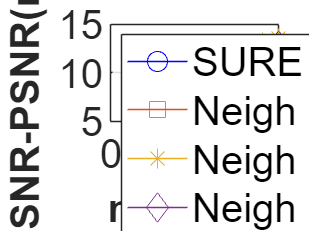

figure
plot(sweep_std,PSNR_sure,'b-o','MarkerSize',10)
hold on
plot(sweep_std,PSNR_neigh,'-s','MarkerSize',10)
hold on
%plot(sweep_std,PSNR_BM3D_standard,'-+','MarkerSize',10)
hold on
plot(sweep_std,PSNR_neigh_complex,'-*','MarkerSize',10)
hold on
%plot(sweep_std,PSNR_BM3D_complex_2nd,'-.','MarkerSize',10)
hold on
%plot(sweep_std,PSNR_BM3D_complex,'-x','MarkerSize',10)
hold on
plot(sweep_std,PSNR_neigh_complex_real_imag,'-d','MarkerSize',10)
set(gca,'fontsize', 20) 

% legend('SURE','Neigh','BM3D standard','Neigh complex','BM3D complex 2nd','BM3D complex','Neigh complex seperate','Location','northwest', ...
%     'FontSize',12)
legend('SURE','Neigh','Neigh complex','Neigh complex seperate','Location','northwest', ...
     'FontSize',20)
xlabel('noise std','FontSize',20,'FontWeight','bold')
ylabel('PSNR-PSNR(noisy)','FontSize',20,'FontWeight', 'bold')


grid on

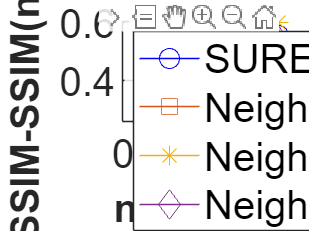

figure
plot(sweep_std,SSIM_sure,'b-o','MarkerSize',10)
hold on
plot(sweep_std,SSIM_neigh,'-s','MarkerSize',10)
hold on
%plot(sweep_std,SSIM_BM3D_standard,'-+','MarkerSize',10)
hold on
plot(sweep_std,SSIM_neigh_complex,'-*','MarkerSize',10)
hold on
%plot(sweep_std,SSIM_BM3D_complex_2nd,'-.','MarkerSize',10)
hold on
%plot(sweep_std,SSIM_BM3D_complex,'-x','MarkerSize',10)
hold on
plot(sweep_std,SSIM_neigh_complex_real_imag,'-d','MarkerSize',10)
set(gca,'fontsize', 20) 

% legend('SURE','Neigh','BM3D standard','Neigh complex','BM3D complex 2nd','BM3D complex','Neigh complex seperate','Location','northwest', ...
%     'FontSize',12)
legend('SURE','Neigh','Neigh complex','Neigh complex seperate','Location','northwest', ...
     'FontSize',20)
xlabel('noise std','FontSize',20,'FontWeight','bold')
ylabel('SSIM-SSIM(noisy)','FontSize',20,'FontWeight', 'bold')


grid on